clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Three-step with alpha = 0


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},0);

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =   -3.7230 + 0.0000i  -0.1570 + 0.5455i  -0.1570 - 0.5455i  -3.7410 + 0.0000i  -0.1672 + 0.5510i  -0.1672 - 0.5510i  -3.6909 + 0.0000i  -0.1730 + 0.5548i  -0.1730 - 0.5548i  -3.6894 + 0.0000i  -0.1738 + 0.5593i  -0.1738 - 0.5593i


Eigenvalues of the coupled systems are all negative 


ans =   -3.4587 + 0.0000i  -3.3013 + 0.0000i  -3.2463 + 0.0000i  -3.1610 + 0.0000i  -0.2945 + 0.7349i  -0.2945 - 0.7349i  -0.3686 + 0.8275i  -0.3686 - 0.8275i  -0.4083 + 0.8539i  -0.4083 - 0.8539i  -0.4380 + 0.8739i  -0.4380 - 0.8739i


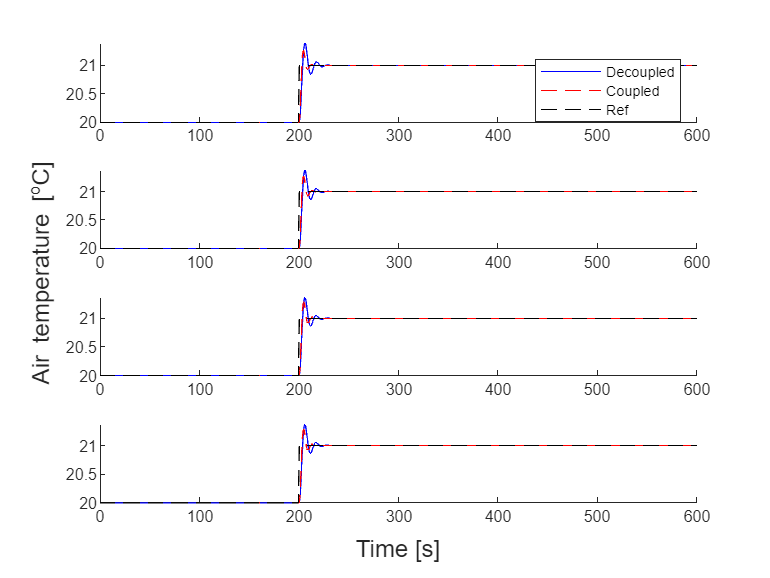

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha0",0);

util.CalculatePerformanceLPV(param,{[-1,1]});

Gamma = 1.9294

ActualGamma = 1.9111

## Three-step with alpha = 0.5


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},.5);

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =   -1.1237 + 1.5698i  -1.1237 - 1.5698i  -1.7895 + 0.0000i  -1.1805 + 1.6503i  -1.1805 - 1.6503i  -1.7145 + 0.0000i  -1.2099 + 1.7193i  -1.2099 - 1.7193i  -1.6172 + 0.0000i  -1.1941 + 1.6781i  -1.1941 - 1.6781i  -1.6487 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -1.4574 + 2.9363i  -1.4574 - 2.9363i  -1.4895 + 3.4703i  -1.4895 - 3.4703i  -1.5111 + 3.6750i  -1.5111 - 3.6750i  -1.5066 + 3.7992i  -1.5066 - 3.7992i  -1.1305 + 0.0000i  -1.0585 + 0.0000i  -1.0437 + 0.0000i  -1.0243 + 0.0000i


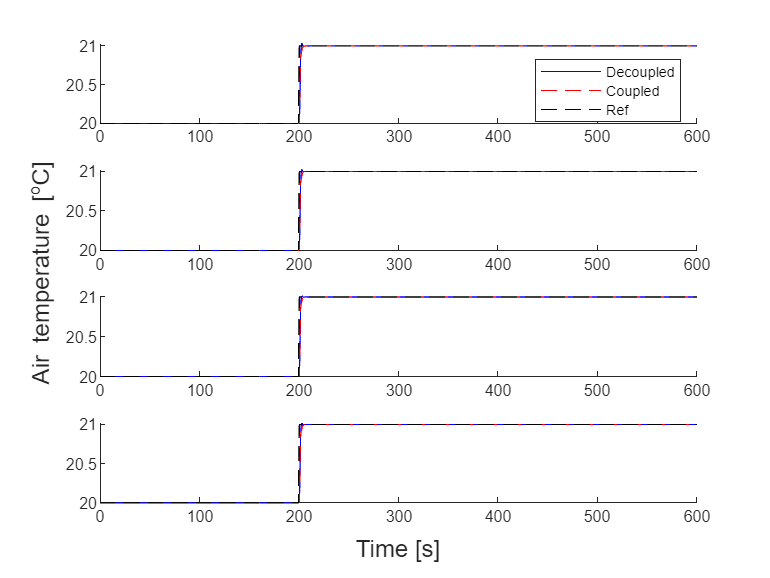

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha",0);

util.CalculatePerformanceLPV(param,{[-1,1]});

Gamma = 1.2569

ActualGamma = 1.2838

## ILMI algorithm


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF_ILMI(param,0,{[-1,1]});

alpha_min = -0.1341

Evaluation of design procedure for ILMI SOF 
Solved the problem in 1 iterations
The solution had alpha: -0.134079 
Eigenvalues of the decoupled systems are all negative 


ans =    -3.4840   -0.4553   -0.0976   -3.4354   -0.5319   -0.1081   -3.4087   -0.5155   -0.1128   -3.4100   -0.5179   -0.1090


Eigenvalues of the coupled systems are all negative 


ans =   -2.7746 + 0.0000i  -1.9843 + 0.8617i  -1.9843 - 0.8617i  -1.9694 + 0.9248i  -1.9694 - 0.9248i  -1.1716 + 0.0000i  -1.9722 + 0.3801i  -1.9722 - 0.3801i  -0.0890 + 0.0000i  -0.1021 + 0.0000i  -0.0991 + 0.0000i  -0.0981 + 0.0000i


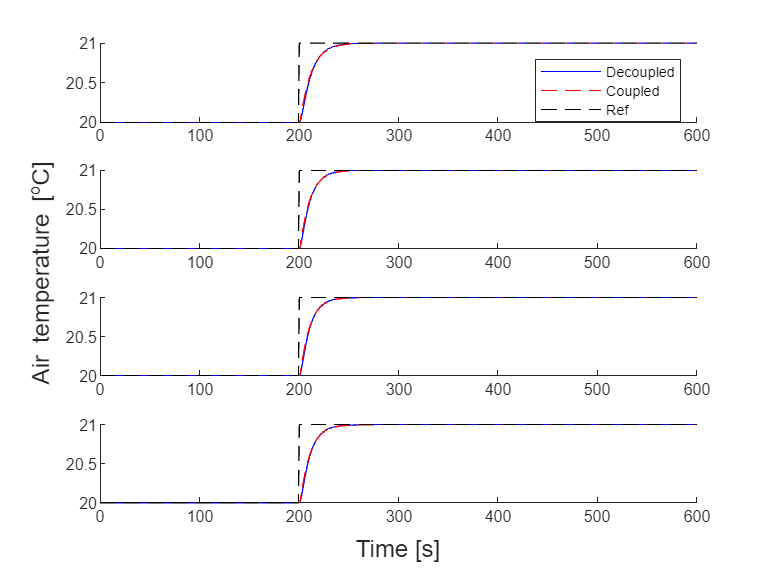

util.SimulateLinearStep(param,"Examination_Output_Feedback_ILMI",0);

util.CalculatePerformanceLPV(param,{[-1,1]});

Gamma = 1.0696

ActualGamma = 1.0758